clearvars
close all
clc

# Inverse Dynamics of Cart Pole System

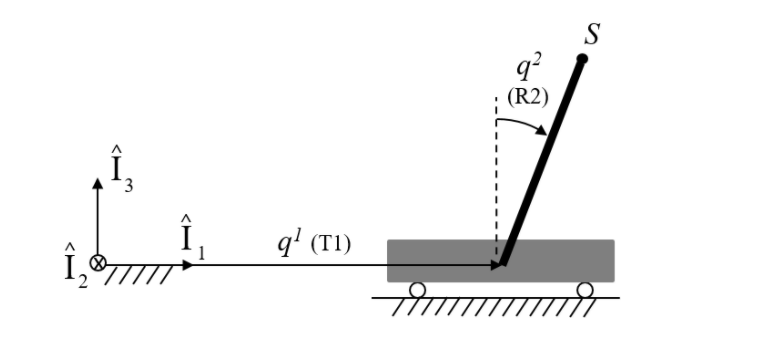

## System Description

The cart translates with respect to the inertial frame in one dimension freely and no external force is applied on the cart. The cart is assumed to be a simple lumped mass block and its inertia and mass is significanty higher than the mass of the pole. This ensures that the motion of the pole doesn't effect the motion of the cart in any way.

The pole is a uniformly distributed stick with its centre of mass at its geometric centre. It rotates with respect to the translating cart with the help of a revolute joint. The system is a lumped parameter system which can be represented by ordinary differential equations.

**The angular motion of the pole is assumed to be very small in order to linearlize the system.**

For this example, the angular motion of the pole is taken as:

#### $\theta = 0.005\cdot \sin {t}  $ (radians), the angle is purposefully kept very small so as to consider small angle approximation in the final analytical expression

The time vector is defined from 0 to 1000 seconds with a time step of 10 seconds.

%time vector
t_span = linspace(0,10,1000);

## System Parameters:

Since it is mentioned that for the dynamic formulation to work, the base has to be inertially very significant to the manipulator, the cart mass is taken as a large value, But logically, cart mass doesn't matter because the pole joint only has to drive the pole and thus the **cart mass won't have any effects on the dynamics**.

#### 
$$m_{Cart} = 1000 kg$$


#### 
$$m_{Pole} = 50 kg$$


#### 
$$l_{Pole} = 0.1 m$$


%cart mass
M = 10000;%kg

%KEpole = 0.5m*v2 + 0.5*I*w2
%I = (1/12)*m*l2;

%Pole mass
m = 50;%kg

%Pole length
L = 0.1;%meters

%pole rotation
theta = 0.005*sin(t_span);%radians

%pole rotation acceleration
theta_dotdot = -0.005*sin(t_span);%radians/second^2

## **System Equation of Motion:**

The dynamics of the system can be solved for using the tradiational Euler Lagrange Approoach:

**Kinetic Energy of System:**

#### 
$$\frac{1}{2}m_{pole}V_{PoleCOM}^{2} + \frac{1}{2}I_{PoleCOM}\omega_{Pole}^2 + \frac{1}{2}m_{Cart}\dot{x}_{Cart}^2$$


#### Potential Energy of the System:

#### 
$$-\frac{m_{Pole}gl_{Pole}}{2}\cos\theta$$


#### Lagrangian of the system:

#### 
$$L = $$

$$\frac{1}{2}m_{pole}V_{PoleCOM}^{2} + \frac{1}{2}I_{PoleCOM}\omega_{Pole}^2 + \frac{1}{2}m_{Cart}\dot{x}_{Cart}^2 + \frac{m_{Pole}gl_{Pole}}{2}\cos\theta$$


#### Euler-Lagrange Equation of the system:

#### 
$$\frac{d}{dt}\left(\frac{\partial L}{\partial \dot{q}}\right) - \frac{\partial L}{\partial q} = Q(t)$$


#### Equation of Motion (assuming small pole joint rotations):

#### 
$$(m_{Cart} + m_{Pole})\ddot{x}_{Cart} - m_{Pole}l_{Pole}\ddot{\theta} = 0$$


#### 
$$\frac{m_{Pole}l_{Pole}^2}{3}\ddot{\theta} - m_{Pole}l_{Pole}\ddot{x_{Cart}} + \frac{m_{Pole}gl_{Pole}}{2}\theta = Q(t)$$


**Based on the equation of motion, the cart trajectory and its derivatives can be computed:**

#### 
$$\ddot{x}_{Cart} = \left(\frac{m_{Pole}l_{Pole}}{m_{Cart} + m_{Pole}}\right)\ddot{\theta}$$


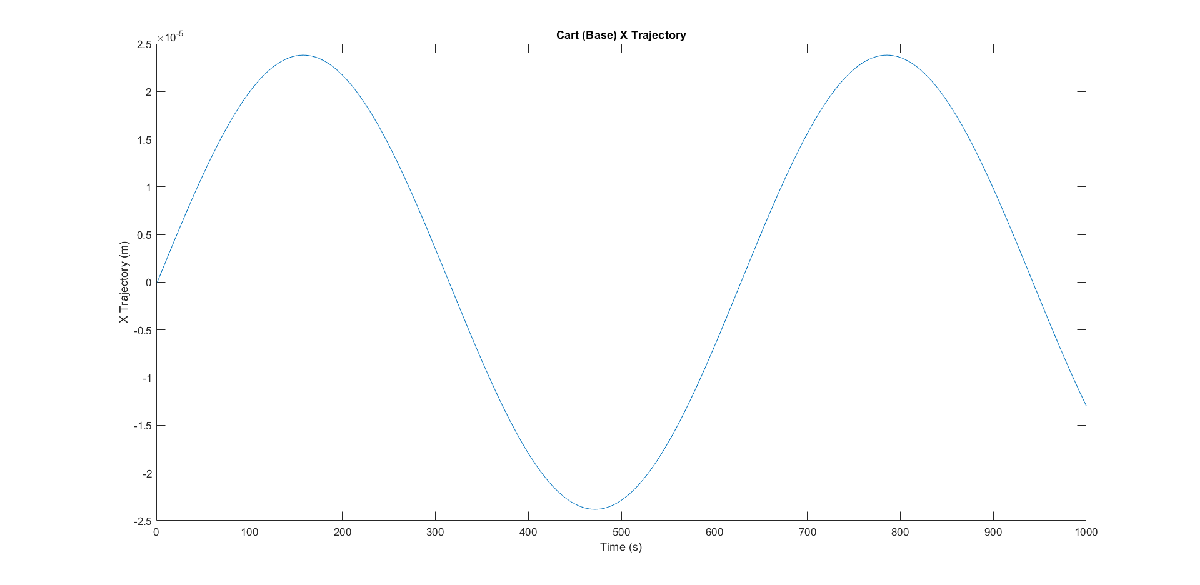


$$$$


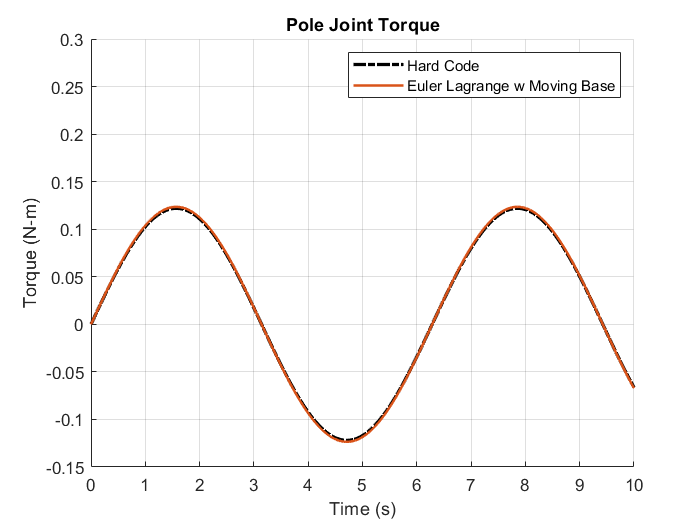

%cart acceleration
x_dotdot = ((m*L)/(m + M))*theta_dotdot;%meters/second^2

%acceleration due to gravity
g = 9.81; %meters/second^2


%Revolute joint torque calculation

torque = ((m*L^2)/(4))*theta_dotdot - (m*L)*x_dotdot + ((m*g*L)/(2))*theta;

%torque calculation from euler lagrange formulation 

code_torques = Inv_Dynamics_LE_CartPole;

figure(1)
hold on
plot(t_span,torque,'-.','color','k','linewidth',2)
plot(t_span,code_torques,'linewidth',1.5)
legend('Hard Code','Euler Lagrange w Moving Base')

grid on
title('Pole Joint Torque')
xlabel('Time (s)')
ylabel('Torque (N-m)')
axis([0,10,-0.15,0.3])